# **LAB:  Bearing Fault Monitoring and RUL Estimation**

**Name: Park Jeong Woo**

**Due in 1 week**

## **Instruction**

In this LAB, you are required to create a simple code for Fault Monitoring and RUL estimation

You can refer to RUL estimation tutorial codes and related papers

**Fault Monitoring**

- Detect Fault Status

- Display WARNING MESSAGE

**RUL Estimation **

- Estimate RUL similar to Tutorial codes

- The end of Life can be assumed when the repair is done

## Dataset

Raw Dataset of Bearing Velocity measured that shows a Bearing Life cycle before the repair is done. Also the velocity measurement after the repair is provided.

Using the given dataset, develop simple program for

- Bearing velocity measured 24 times per day

- Each measurement is L=8192 with Fs=2560Hz  

- Measurement for consecutive days until repair is done

First visualize the vibration signals in the time domain. 

clear; close all; clc;

%load("RULdata/bearing_vel_fulldata.mat");
load("bearing_vel_fulldata.mat");
% rows: vel measurements // cols: measurement time 
% idx_repair = 1431;
bearing=bearingFulldata(:,1:idx_repair);
bearingNew=bearingFulldata(:,idx_repair+1:end);

% Data Length for each measurement
% L=8192
L=length(bearing(:,1))

L = 8192


% Sampling Frequency
fs = 2560;
ts = 1/fs;
t = 0:ts:ts*(L-1);


% Day(time) unit upto repair
dataN=(length(bearing(1, :)));
d = (0:1:dataN)/24;



Plotting bearing velocity raw data

- Initial state:  Day=0 

- Just before repair:  Day=59

- After repair:  Day=60

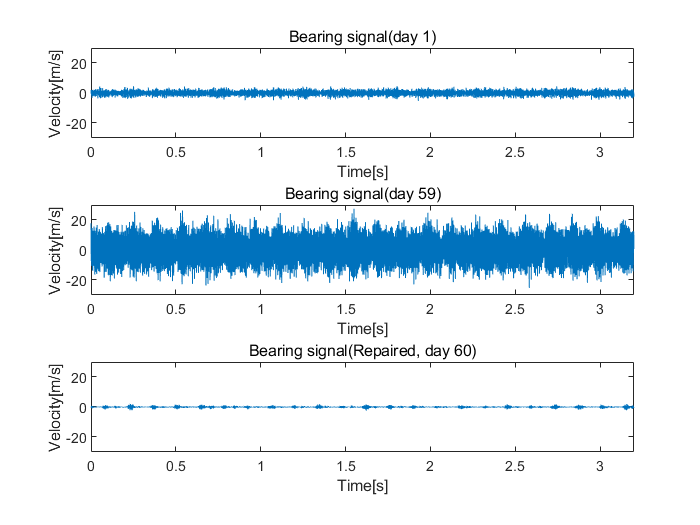

idx1 = 1;   idx2 = idx_repair;    idx3 = 1;

figure
subplot(3, 1, 1);       plot(t, bearing(:, idx1));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(day 1)');
subplot(3, 1, 2);       plot(t, bearing(:, idx2));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(day 59)');
subplot(3, 1, 3);       plot(t, bearingNew(:, idx3));
xlim([0 3.2]);  ylim([-30 30]); xlabel('Time[s]');  ylabel('Velocity[m/s]');    title('Bearing signal(Repaired, day 60)');

## **Data Exporation and Preprocessing**

You need to explain the process cleary and analyze the results

Because the shaft is not continuously rotating, it temporarily shows zero when the shaft stops in raw data.

It can be clearly seen when looking at the daily RMS change using raw data.

In order to eliminate this phenomenon, since the above data is time series data, the previous data value was input to data with an RMS value of 0.5 or less.

Looking at the RMS with preprocessed data, there was no peak.

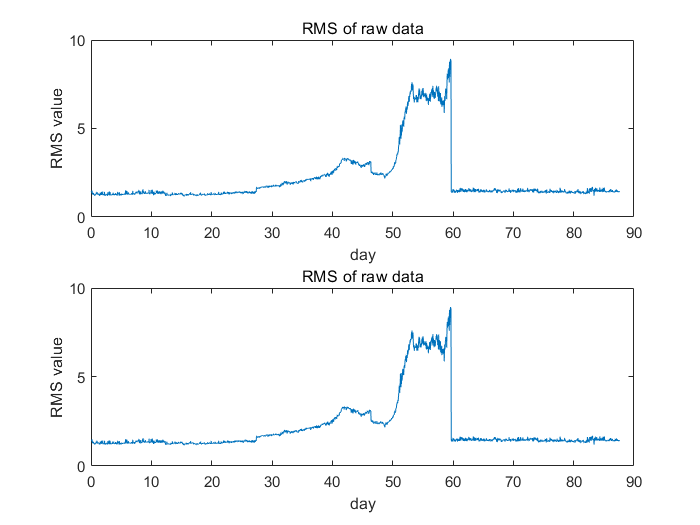

%%% YOUR CODE GOES HERE
%Preprocessing
data_idx = width(bearingFulldata);
day = 24;
date = (1:data_idx)/day ;

RMS_bf = rms(bearingFulldata(:,1:data_idx));
redu_idx = find(RMS_bf < 0.5);

for i = 1:length(redu_idx)

    bearingFulldata(:,redu_idx(i)) = bearingFulldata(:,redu_idx(i)-1);

end

RMS_af = rms(bearingFulldata(:,1 : data_idx));

figure
subplot(2,1,1);
plot(date,RMS_bf);
title('RMS of raw data');
xlabel('day');
ylabel('RMS value');

subplot(2,1,2);
plot(date,RMS_af);
title('RMS of raw data');
xlabel('day');
ylabel('RMS value');

## **- Feature Extraction and Analysis**

You need to explain the process cleary and analyze the results

In addition to RMS, the following features were examined to see the characteristics according to the bearing's life tendency.

When learning, more accurate results can be obtained only when learning is performed by selecting a characteristic with clear features.

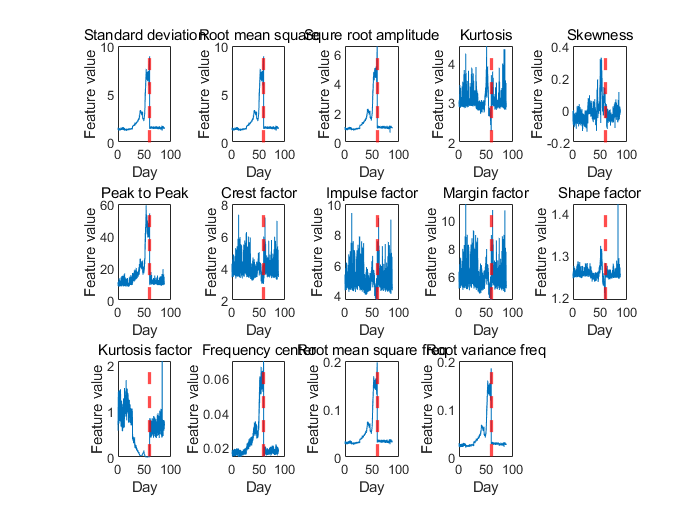

%%% YOUR CODE GOES HERE
name = ["Standard deviation","Root mean square", "Squre root amplitude", "Kurtosis","Skewness","Peak to Peak"...
        "Crest factor", "Impulse factor", "Margin factor", "Shape factor", "Kurtosis factor"...
        "Frequency center", "Root mean square freq", "Root variance freq"];
[Feature, freq] = get_feature(bearingFulldata);

figure
for i = 1:14
    subplot(3,5,i);
    plot(date,Feature(:,i))
    title(name(i));
    xlabel('Day');
    ylabel('Feature value');
    xline(60,'--r','LineWidth',2);
end

###  FFT 

At frequencies 150 to 190 Hz (Narrow Band) related to the failure of the bearing, the magnitude of the frequency has changed, but due to frequency components other than the failure characteristics, the value of the entire RMS does not change significantly. Therefore, RMS can be said to be a feature with low monotonicity.

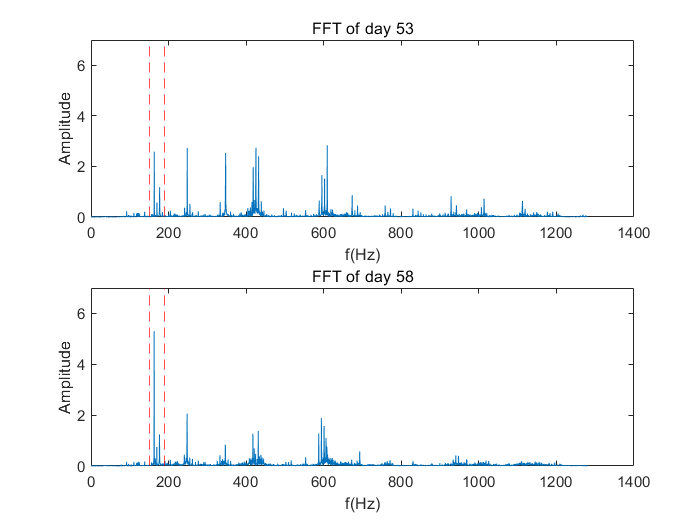

f = 0:fs/L:fs/2;
day_53 = 53*24+1;

day_58 = 58*24+1;

figure

subplot(2,1,1)
plot(f,freq(:,day_53))
title('FFT of day 53')
xlabel('f(Hz)')
ylabel('Amplitude')
xline(150,'--r','LineWidth',0.1);
xline(190,'--r','LineWidth',0.1);
ylim([0,7])

subplot(2,1,2)
plot(f,freq(:,day_58))
title('FFT of day 58')
xlabel('f(Hz)')
ylabel('Amplitude')
xline(150,'--r','LineWidth',0.1);
xline(190,'--r','LineWidth',0.1);
ylim([0,7])

### Day 1, 59 and 60 of FFT

The corresponding figure was added to compare FFT before and after the bearing failed, and to see that the frequency changed when the bearing failed.

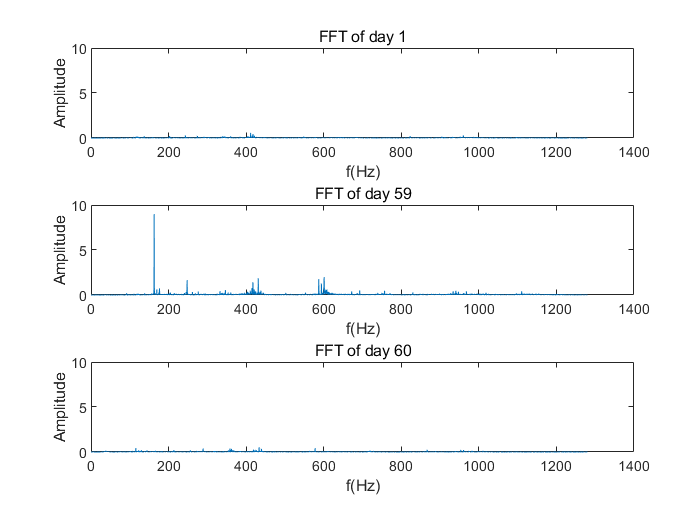

day_1 = 1;
day_59 = 59*24+1;
day_60 = 60*24+1;

figure

subplot(3,1,1)
plot(f,freq(:,day_1))
title('FFT of day 1')
xlabel('f(Hz)')
ylabel('Amplitude')
ylim([0,10])

subplot(3,1,2)
plot(f,freq(:,day_59))
title('FFT of day 59')
xlabel('f(Hz)')
ylabel('Amplitude')
ylim([0,10])

subplot(3,1,3)
plot(f,freq(:,day_60))
title('FFT of day 60')
xlabel('f(Hz)')
ylabel('Amplitude')
ylim([0,10])

### FFT over time

 In this step, let's take a look at how the frequency changes over time to confirm, the results were confirmed through FFT for each day.

Looking at the figure below, it was confirmed that there was a change in frequency over time and that the failure frequency was not visible again after repair.

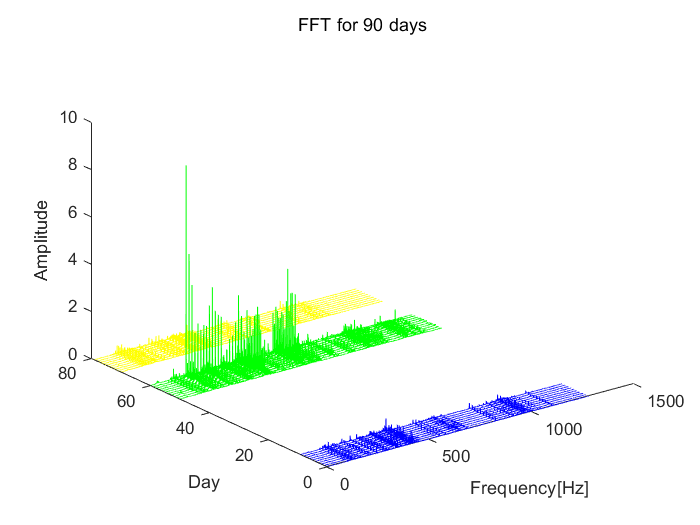

figure

zero = zeros(1,4097);
for i = 1:24:240

    plot3(f,(zero + i)/24,freq(:,i),'b')
    hold on
    ylim([0,80])
    zlim([0,10])
end

for i = 50*24+1 : 24 : 60*24+1
    plot3(f,(zero + i)/24,freq(:,i),'g')
end
for i = 70*24+1 : 24 : 80*24+1
    plot3(f,(zero + i)/24,freq(:,i),'y')
end
xlabel('Frequency[Hz]')
ylabel('Day')
zlabel('Amplitude')
title('FFT for 90 days')
hold off

### Bearing Velocity Envelop FFT

When FFT was performed, frequency analysis was difficult due to other frequency components, so frequency analysis was performed through the envelope technique.

However, it is difficult to find the frequency characteristics according to the day as below, so the envelope feature is not used.

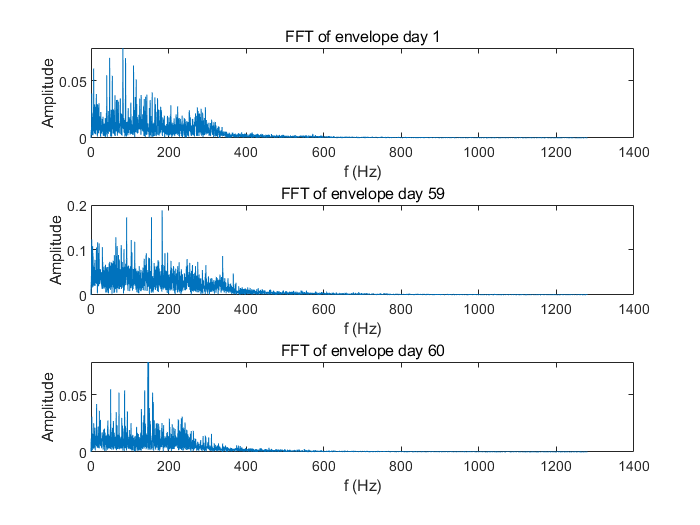

[pEnv, fEnv, a , b] = envspectrum(bearingFulldata,fs);

figure
% Plot
figure
subplot(3, 1, 1)
plot(fEnv, pEnv(:,1))

xlabel('f (Hz)')
ylabel('Amplitude')
title('FFT of envelope day 1')

subplot(3, 1, 2)
plot(fEnv, pEnv(:,24*59+1))

xlabel('f (Hz)')
ylabel('Amplitude')
title('FFT of envelope day 59')

subplot(3, 1, 3)
plot(fEnv, pEnv(:,24*60+1))

xlabel('f (Hz)')
ylabel('Amplitude')
title('FFT of envelope day 60')

### Narrowband Energy over time

Frequency RMS, STD and ect at frequencies 150 to 190 Hz (Narrow Band) related to bearing failure were obtained.

The graph below is a significant feature because it has the characteristics of monotonicity that goes up right every day.

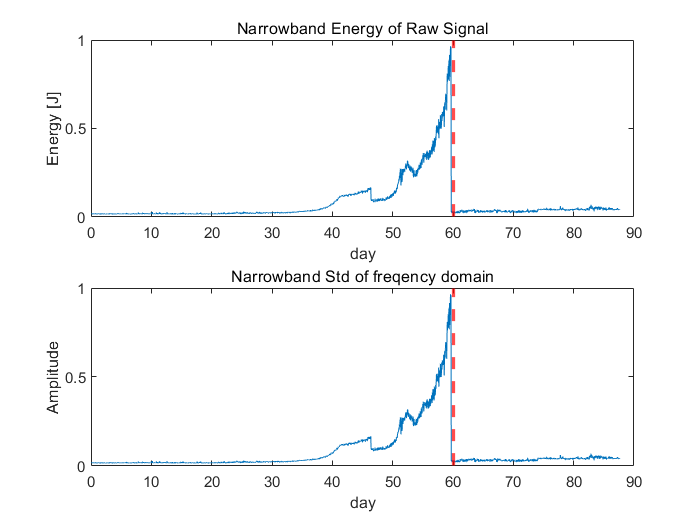

rms_narrow_idx = find(f >= 150 & f <= 190);
Narrowband_energy = rms(freq(rms_narrow_idx,:));
Narrowband_std = std(freq(rms_narrow_idx,:));
NB_freq_feature = [Narrowband_energy' Narrowband_std'];

[~ ,~ ,NB_freq ] = get_feature(bearingFulldata(rms_narrow_idx,:));

figure
subplot(2,1,1)
plot(date,Narrowband_energy)
xline(60,'--r','LineWidth',2);
xlabel('day')
ylabel('Energy [J]')
title('Narrowband Energy of Raw Signal')

subplot(2,1,2)
plot(date,Narrowband_energy)
xline(60,'--r','LineWidth',2);
xlabel('day')
ylabel('Amplitude')
title('Narrowband Std of freqency domain')

### Spectral kurtosis over time

Spectral Kurtosis was analyzed over time. In the previous analysis, kurtosis had poor monotonicity.

 Similarly, Spectral Kurtosis also shows that the frequency continues to change despite repairs on day 60.

In this analysis, it can be expected that monotonicity will not be good.

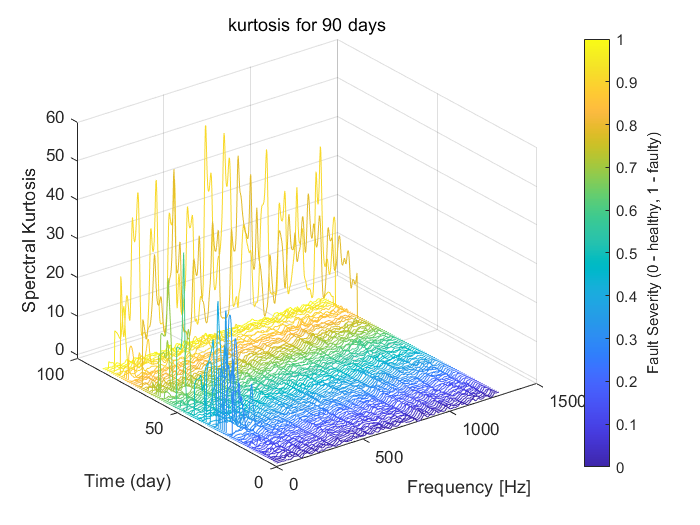

raw_bearing = [bearing bearingNew];
idx = 1;
colors = parula(2104);
figure

for i = 1:24:2104
   data2add = table;
  
     % Compute spectral kurtosis with window size = 128
    wc = 128;
    [SK, F] = pkurtosis(raw_bearing(:,i), fs, wc);
    data2add.SpectralKurtosis = {table(F, SK)};
    plot3(F, (i*ones(size(F)))/24, SK, 'Color', colors(i, :))
    zlim([-1, 60])
    sk(:,idx) = SK;
    idx = idx+1;
    grid on
    hold on
end
xlabel('Frequency [Hz]')
ylabel('Time (day)')
zlabel('Sperctral Kurtosis')
cbar = colorbar;
ylabel(cbar, 'Fault Severity (0 - healthy, 1 - faulty)')
title('kurtosis for 90 days')

SKmean = mean(sk);
SKstd = std(sk);
SKskewness = skewness(sk);
SKkurtosis = kurtosis(sk);

SK_feature = [SKmean' SKstd' SKskewness' SKkurtosis'];

## **Selection of Features**

You need to explain the process cleary and analyze the results

In order to learn data, the data obtained in the previous process is made into a table over time.

feature_name_time = ["STD","RMS", "SRA", "Kurtosis", "Skewness","P2P", "CrestFactor", "ImpulseFactor",...
                "MarginalFactor", "ShapeFactor", "KurtosisFactor"];

feature_name_freq    = ["Frequency Center", "Frequency RMS", "Frequency RMS Varience"] ; 
feature_name_freq_NB = ["NB " + feature_name_freq "NB freq energy" "NB freq std"];
feature_name_SK = ["SKmean", "SKstd", "SKskewness","SKkurtosis"];

%SK_feature = [SKmean' SKstd' SKskewness' SKkurtosis'];

name = [feature_name_time feature_name_freq feature_name_freq_NB feature_name_SK];

date_real =(datetime(2021,4,14):days(1):datetime(2021,7,11));
datetim = (date_real(2:61)); %60 days

feature = [Feature(1:24:idx_repair, :) table2array(NB_freq(1:24:idx_repair, :))...
            NB_freq_feature(1:24:idx_repair, :) SK_feature(1:60,:)];

featureTable = array2table(feature, "VariableNames",name );

featureTable = table2timetable(featureTable,'RowTimes',datetim)

featureTable = 60×23 timetable
       Time        STD       RMS        SRA      Kurtosis     Skewness      P2P     CrestFactor    ImpulseFactor    MarginalFactor    ShapeFactor    KurtosisFactor    Frequency Center    Frequency RMS    Frequency RMS Varience    NB Frequency Center    NB Frequency RMS    NB Frequency RMS Varience    NB freq energy    NB freq std     SKmean      SKstd     SKskewness    SKkurtosis
    __________    ______    ______    _______    ________    __________    _____    ___________    _____________    ______________    ___________    ______________    ________________    _____________    ______________________    ___________________    ________________    _________________________    ______________    ___________    ________    _______    __________    __________

    2021-04-15    1.3984    1.3983    0.94351      2.963      -0.070809     9.81      3.7331          4.6799            5.5325          1.2536          0.77504             0.01698          0.030895     

### Feature Postprocessing

Because of the noisy signal, the characteristics cannot be checked properly, so Smoothing is performed using the media filter.

The average is calculated with seven data and Smoothing is performed.

The graph below shows before and after the filter. It can be confirmed that it has been filtered normally and the result of Smoothing will be learned.

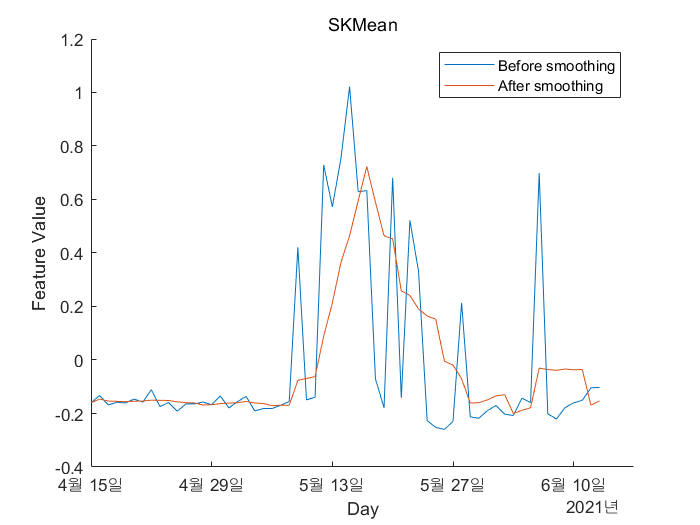

variableNames = featureTable.Properties.VariableNames;
featureTableSmooth = varfun(@(x) movmean(x, [5 0]), featureTable); %smoothing
featureTableSmooth.Properties.VariableNames = variableNames;

figure
hold on
plot(featureTable.Time, featureTable.SKmean)
plot(featureTableSmooth.Time, featureTableSmooth.SKmean)
hold off
xlabel('Day')
ylabel('Feature Value')
legend('Before smoothing', 'After smoothing')
title('SKMean')

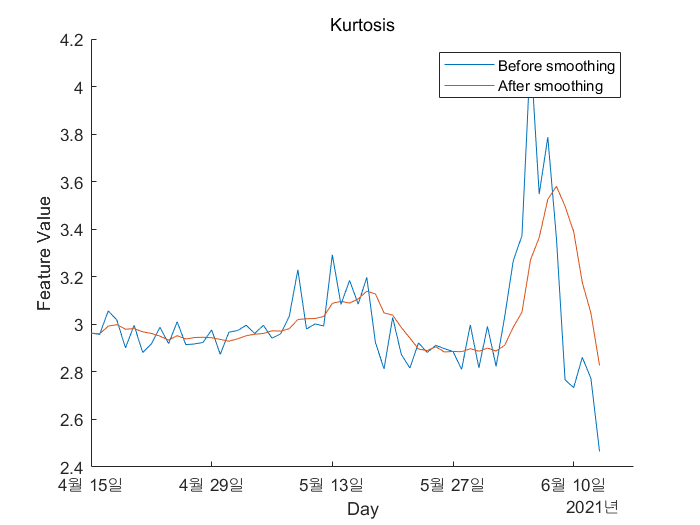


figure
hold on
plot(featureTable.Time, featureTable.Kurtosis)
plot(featureTableSmooth.Time, featureTableSmooth.Kurtosis)
hold off
xlabel('Day') 
ylabel('Feature Value')
legend('Before smoothing', 'After smoothing')
title('Kurtosis')

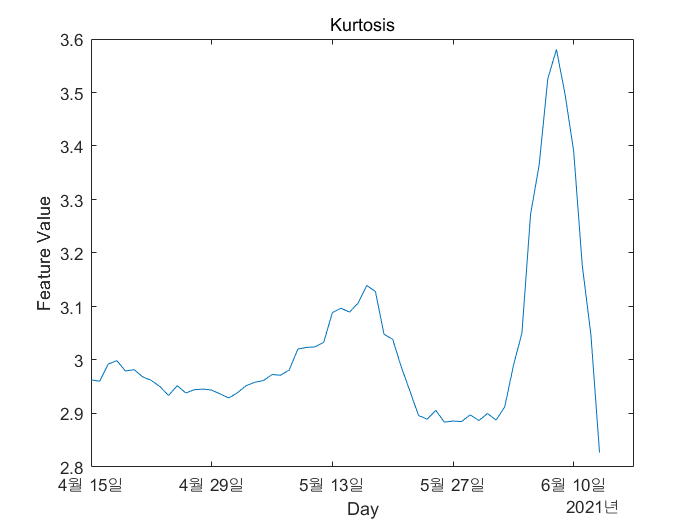


% Plot some features over time after applying smoothing
figure
plot(featureTableSmooth.Time, featureTableSmooth.Kurtosis)
hold off
xlabel('Day')
ylabel('Feature Value')
title('Kurtosis')

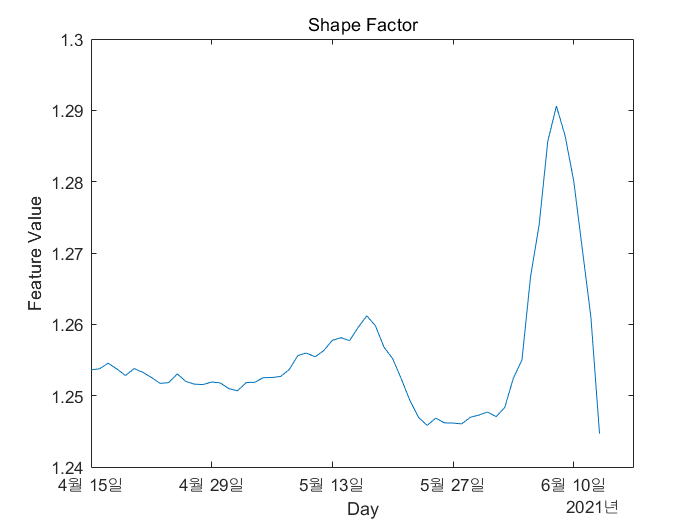


figure
plot(featureTableSmooth.Time, featureTableSmooth.ShapeFactor)
hold off
xlabel('Day')
ylabel('Feature Value')
title('Shape Factor')

### Training Data

From April 15th to May 15th, about 50% of the total data set is a training set.

breaktime = datetime(2021, 5, 15);
breakpoint  = find(featureTableSmooth.Time  < breaktime , 1, 'last');   % 60 * 0.4 = 24 days

trainData   = featureTableSmooth(1:breakpoint, :)

trainData = 30×23 timetable
       Time        STD       RMS        SRA      Kurtosis    Skewness      P2P      CrestFactor    ImpulseFactor    MarginalFactor    ShapeFactor    KurtosisFactor    Frequency Center    Frequency RMS    Frequency RMS Varience    NB Frequency Center    NB Frequency RMS    NB Frequency RMS Varience    NB freq energy    NB freq std     SKmean      SKstd     SKskewness    SKkurtosis
    __________    ______    ______    _______    ________    _________    ______    ___________    _____________    ______________    ___________    ______________    ________________    _____________    ______________________    ___________________    ________________    _________________________    ______________    ___________    ________    _______    __________    __________

    2021-04-15    1.3984    1.3983    0.94351      2.963     -0.070809      9.81      3.7331          4.6799            5.5325          1.2536          0.77504             0.01698          0.030895        

### Feature Importance Ranking

Select the monotonicity for each feature of the train data and select the data to be learned. 

I selected a total of 5 features of 0.2 or more.

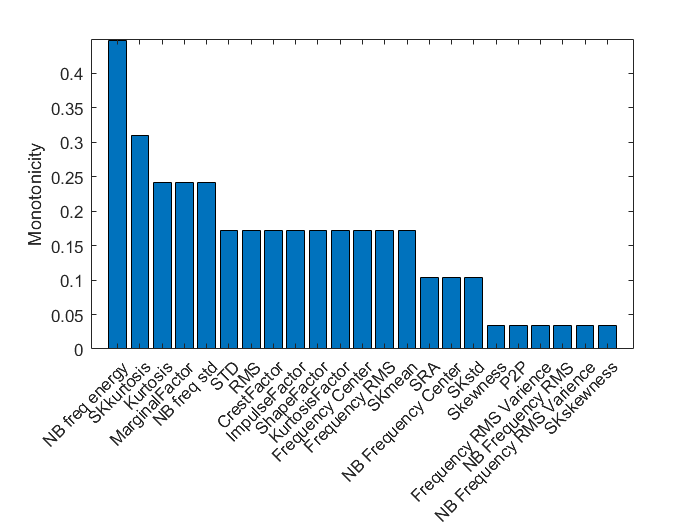

ans =     18    23     4     9    19     1     2     7     8    10    11    12    13    20     3    15    21     5     6    14    16    17    22


featureImportance = monotonicity(trainData, 'WindowSize', 0);
helperSortedBarPlot(featureImportance, 'Monotonicity')

### Dimension Reduction and Feature Fusion

Features with high monotonicity are selected and Dimension reduction is performed using PCA.

A total of four normal vectors of PCA can be obtained, of which only two were plotted, and PCA1 and 2 had a similar graph form.

I chose PCA1 as the health indicator among them.

trainDataSelected = trainData(:, featureImportance{:,:}>=0.2);
featureSelected = featureTableSmooth(:, featureImportance{:,:}>=0.2);

meanTrain = mean(trainDataSelected{:,:});
sdTrain = std(trainDataSelected{:,:});

trainDataNormalized = (trainDataSelected{:,:} - meanTrain)./sdTrain;
coef = pca(trainDataNormalized);

PCA1 = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 1);
PCA2 = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 2);

timeUnit = 'day';

Visualize the data in the space of the first two principal components.

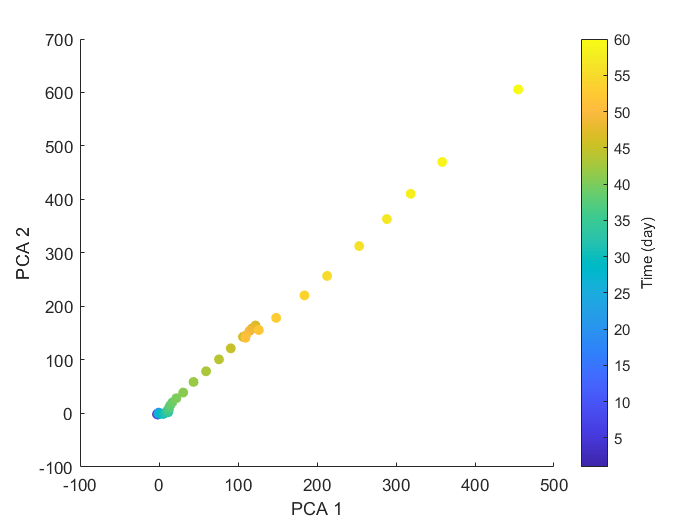

figure
numData = size(featureTable, 1);
scatter(PCA1, PCA2, [], 1:numData, 'filled')
xlabel('PCA 1')
ylabel('PCA 2')
cbar = colorbar;
ylabel(cbar, ['Time (' timeUnit ')'])

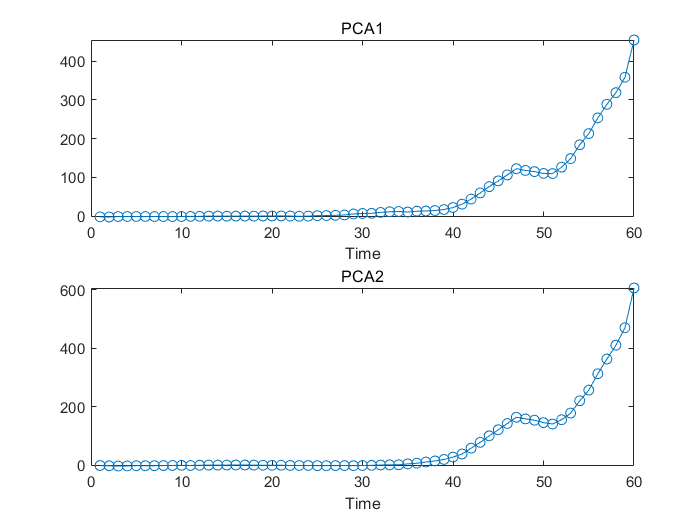

figure
subplot(2,1,1)
plot(PCA1, '-o')
xlabel('Time')
title('PCA1')

subplot(2,1,2)
plot(PCA2, '-o')
xlabel('Time')
title('PCA2')

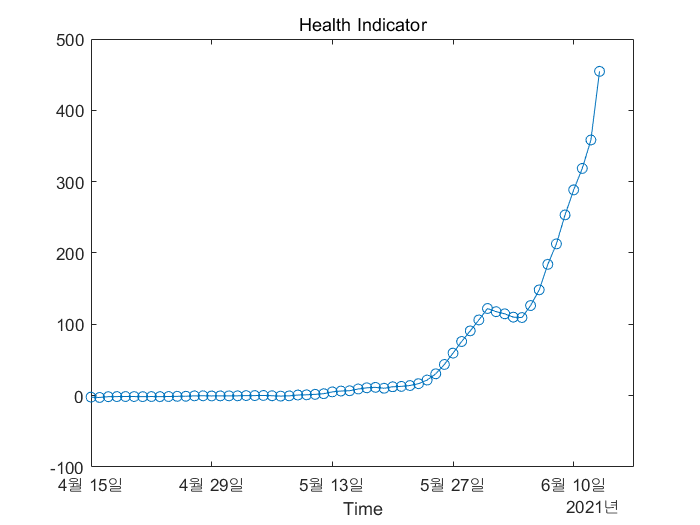

figure
healthIndicator = PCA1;
plot(featureSelected.Time, healthIndicator, '-o')
xlabel('Time')
title('Health Indicator')

## Fault Monitoring and Warning

You need to explain the process cleary and analyze the results

Train data is learned by the experimental gradation model to predict the replacement cycle and life of the bearing. 

It can be interpreted that the bearing has a lifespan of about 3 days after 59 days under normal bearing conditions, compared to the previous analysis data.

It appears that the bearing broke down in about 60 days and has been repaired since then. In other words, by setting the replacement cycle of the bearing to 60 days and giving warning when it approaches 60 days,

It is possible to predict the replacement cycle and lifespan of the bearing.

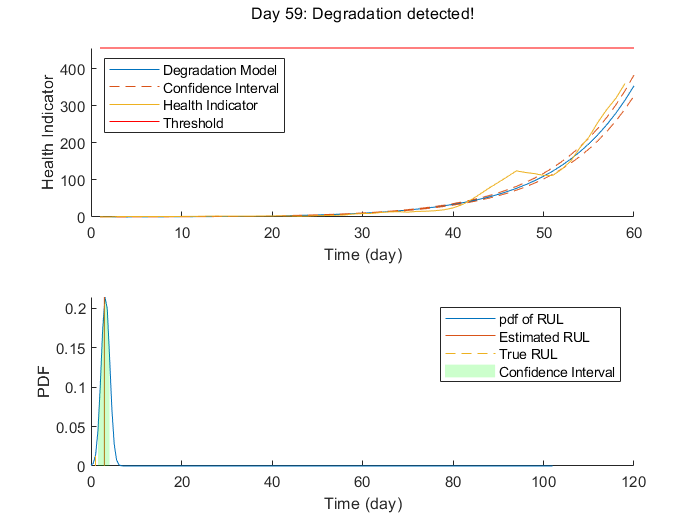

%%% YOUR CODE GOES HERE
healthIndicator = healthIndicator - healthIndicator(1);
threshold = healthIndicator(end);


mdl = exponentialDegradationModel(...
    'Theta', 1, ...
    'ThetaVariance', 1e6, ...
    'Beta', 1, ...
    'BetaVariance', 1e6, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold/(threshold + 1))^2, ...
    'SlopeDetectionLevel', 0.05);


% Keep records at each iteration
totalDay = length(healthIndicator) - 1;
estRULs = zeros(totalDay, 1);
trueRULs = zeros(totalDay, 1);
CIRULs = zeros(totalDay, 2);
pdfRULs = cell(totalDay, 1);

% Create figures and axes for plot updating
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);

for currentDay = 1:totalDay
    
    % Update model parameter posterior distribution
    update(mdl, [currentDay healthIndicator(currentDay)])
    
    % Predict Remaining Useful Life
    [estRUL, CIRUL, pdfRUL] = predictRUL(mdl, ...
                                         [currentDay healthIndicator(currentDay)], ...
                                         threshold);
    trueRUL = totalDay - currentDay + 1;
    
    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, healthIndicator, mdl, threshold, timeUnit);
    helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
    
    % Keep prediction results
    estRULs(currentDay) = estRUL;
    trueRULs(currentDay) = trueRUL;
    CIRULs(currentDay, :) = CIRUL;
    pdfRULs{currentDay} = pdfRUL;
    
    % Pause 0.1 seconds to make the animation visible
    pause(0.1)
end

## RUL Estimation

You need to explain the process cleary and analyze the results

TheFirst, the blue graph shows the remaining life of the bearing over time.

The red graph shows that the accuracy increases as the data is learned. graph below is plotted for RUL estimation. 

And the second graph is a graph showing the probability that the RUL prediction falls into the alpha range. It can be seen that the probability decreases as the day increases.

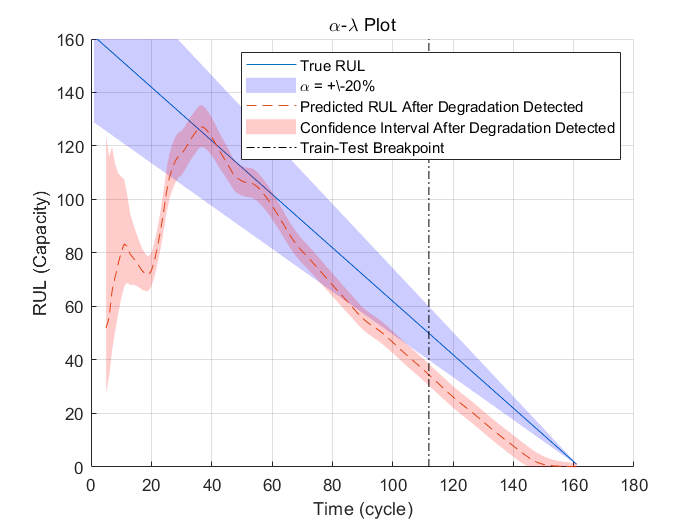

%%% YOUR CODE GOES HERE
alpha = 0.2;
detectTime = mdl.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, trueRULs, estRULs, CIRULs, ...
    pdfRULs, detectTime, breakpoint, timeUnit);
title('\alpha-\lambda Plot')

figure
t = 1:totalDay;

'totalDay'은(는) 인식할 수 없는 함수 또는 변수입니다.

hold on
plot(t, prob)
plot([breakpoint breakpoint], [0 1], 'k-.')
hold off
xlabel(['Time (' timeUnit ')'])
ylabel('Probability')
legend('Probability of predicted RUL within \alpha bound', 'Train-Test Breakpoint')
title(['Probability within \alpha bound, \alpha = ' num2str(alpha*100) '%'])

## Discussion 

This experiment is an experiment that can predict the RUL (Remaining Useful Life) of bearings using time series bearing datasets to confirm implementation monitoring and warning.

Features in the time domain and features in the frequency domain may be obtained by using the characteristics of the time series data.

The monotinity of each feature was checked to select a high value. After that, we used PCA techniques for demonstration reduction

It was possible to predict the RUL of the bearing by learning it through the Elemental Degradation model.

So what we need to do in this experiment is to make a predictive model that's performing well

First, create a dataset using appropriate features. If significant data is selected for prediction and included in the data set, a model with good performance can be made.

Secondly, the amount of train in the data set.

 It can be said to be an important part because the performance of the prediction model varies depending on how much train set is divided. However, it is important to train meaningful data, which is not good to have a lot of data unconditionally.

The last one is monotonicity. When learning the feature, features were used in the order of higher monotonicity, and the higher the monotonicity, the more accurate prediction could be made.  

If you pay attention to the above three points, you will be able to have a good performance model.

## Reference

Rauber, T. W., de Assis Boldt, F., & Varejão, F. M. (2014). Heterogeneous feature models and feature selection applied to bearing fault diagnosis. *IEEE Transactions on Industrial Electronics*, *62*(1), 637-646.